%Note always wrap the diffence of the angles, which is being supplied to
%the controller error.
clear;
clc;

g = 9.81; %m/s^2
va = 15; %m/s
phiMax = 45*pi/180; %radians
psiDotMax = g*tan(phiMax)/va %radians/sec

psiDotMax = 0.6540

kMaxu = psiDotMax/va %m^-1

kMaxu = 0.0436


%Reactangle
l = 75;
m = 37.5;

%Corresponsing Lame' Curve for the rectangle, (n,a,b) calculated for
%minimum path length
narr = 2:0.01:10;
sz = size(narr);
perim = zeros([1, sz(2)]);
an = zeros([1, sz(2)]);
bn = zeros([1, sz(2)]);

i = 1;
while i < sz(2)
    F = @(a) (narr(i)-1)* m * a^narr(i) * (a^narr(i) - l^narr(i)) * l^(narr(i)-2) / (m^2 * l^(2*narr(i)-2) + (a^narr(i) - l^narr(i))^2)^(3/2) - kMaxu;
    a = fzero(F, l+5, optimset('Display','off'));
    if isnan(a)
        i = i+1;
        continue;
    end
    b = a*m/(a^narr(i) - l^narr(i))^(1/narr(i));
    
    perim(i) = peri(narr(i),a,b);
    an(i) = a;
    bn(i) = b;
    i = i + 1;
end

nonzero_indices = find(perim > 0);              % Indices where perim is non-zero
[~, min_idx_rel] = min(perim(nonzero_indices)); % Relative index of min non-zero
min_idx = nonzero_indices(min_idx_rel);         % Actual index in original array
n = narr(min_idx)

n = 4.0600

a = an(min_idx)

a = 81.5890

b = bn(min_idx)

b = 50.8870

S = perim(min_idx)

S = 468.3800




%Initial Position of the UAV
simtime = 50;
h = 0.001;
pos = zeros([5,simtime/h + 1]);

xa = 150; %m
ya = 75; %m
psi = -3*pi/4;
psidot = 0;
ke = 0.5;
kpsi = 100;
kpsidot = 10;

pos(1:2,1) = [xa;ya];
figure;
hold on;
grid on; grid minor;
axis equal;
drawSquare(l,m);
drawLameC(n,a,b);
plot(pos(1,1), pos(2,1), 'o', markersize=8, color='#0000ff', MarkerFaceColor='#0099aa');

i = 2;
for t = 0:h:simtime
    beta = abs(xa/a)^n + abs(ya/b)^n;
    %gradients,
    %where, f = |x / (a*beta^(1/n))|^n + |y / (b*beta^(1/n))|^n - 1
    fx = sign(xa)*n*abs(xa)^(n-1) / (a^n * beta);
    fy = sign(ya)*n*abs(ya)^(n-1) / (b^n * beta);
    fxx = n*(n-1)*abs(xa)^(n-2) / (a^n * beta);
    fyy = n*(n-1)*abs(ya)^(n-2) /(b^n * beta);
    
    psit = atan2(fx ,-fy);
    psio = pi/2 - asin(1/(1+ke*(beta-1)^2));
    psid = wrapToPi(psit + sign(beta - 1)*psio);
    
     %initially
    if t == 0
        pos(3:5,1) = [psi;psidot;beta-1];
    end

    
    psitdot = va*(fx*fyy*sin(psi) - fy*fxx*cos(psi))/(fx^2 + fy^2);
    psiodot = 2*ke*va*(fx*cos(psi) + fy*sin(psi))/((1+ke*(beta-1)^2)*sqrt((ke*(beta-1))^2 + 2*ke));
    psiddot = psitdot + sign(beta-1)*psiodot;

   
    [psi, psidot] = RK4psi(h,kpsi,kpsidot,psid,psi,psiddot,psidot);
    psidot = max(min(psidot, psiDotMax), -psiDotMax);

    xa = xa + va*cos(psi)*h;
    ya = ya + va*sin(psi)*h;

    pos(:,i) = [xa;ya;psi;psidot;beta-1];
    if ~mod(i, 100)
        if i ~= 100
            delete(h1);
            delete(h2);
        end
        h1 = plot(pos(1,1:i), pos(2,1:i), linewidth = 1.5, color='#0099aa');
        h2 = plot(pos(1,i), pos(2,i), 'o', markersize = 8, color = '#0099ff', linewidth=1.5);
        
        pause(h/1000);
    end
    i = i + 1;
end

xlabel("x - Axis");
ylabel("y - Axis");
hold off;


%psi plotting
figure;
t = 0:h:simtime+h;
plot(t, pos(3,:)*180/pi, linewidth=1.5);
hold on;
grid on; grid minor;
xlabel("Time, t (in sec)");
ylabel("Actual Heading Angle, \psi (in degrees)");
title("Variation in Heading angle with time");
hold off;

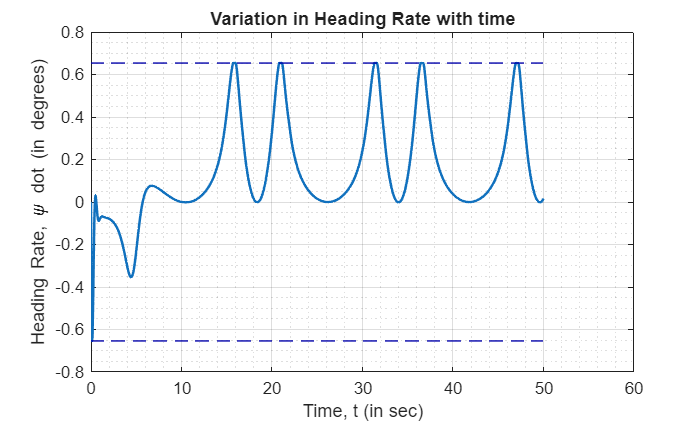


%psidot plotting
figure;
plot(t, pos(4,:), linewidth=1.5);
hold on;
grid on; grid minor;
plot([0, simtime+h], [psiDotMax, psiDotMax], '--', color='#0000aa');
plot([0, simtime+h], [-psiDotMax, -psiDotMax], '--', color='#0000aa');
xlabel("Time, t (in sec)");
ylabel("Heading Rate, \psi dot (in degrees)");
title("Variation in Heading Rate with time");
hold off;

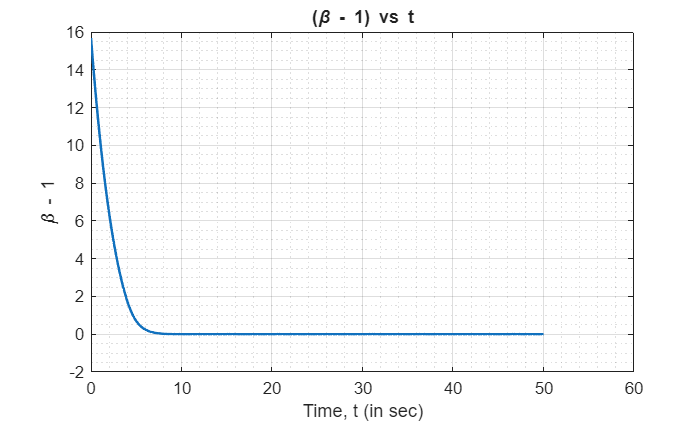

%(beta-1) plotting
figure;
plot(t, pos(5,:), linewidth=1.5);
hold on;
grid on; grid minor;
xlabel("Time, t (in sec)");
ylabel("\beta - 1");
title("(\beta - 1) vs t");
hold off;



function S = peri(n,a,b)
    x1 = a:-0.01:0;
    x2 = -0.01:-0.01:-a;
    x = [x1 x2 flip(x2(2:end)) flip(x1)];
    
    y1 = (b/a) * (a^n - x1.^n).^(1/n);
    y2 = (b/a) * (a^n - (-x2).^n).^(1/n);
    y = [y1 y2  flip(-y2(2:end)) flip(-y1)];

    dx = diff(x);
    dy = diff(y);
    S = sum(sqrt(dx.^2 + dy.^2));  % Euclidean segment lengths
end

function drawSquare(a, b)
    x = [a, -a, -a, a, a];
    y = [b, b, -b, -b, b];

    plot(x,y, linewidth=1.5);
end
function drawLameC(n,a,b)
    x1 = a:-0.01:0;
    x2 = -0.01:-0.01:-a;
    x = [x1 x2 flip(x2(2:end)) flip(x1)];
    
    y1 = (b/a) * (a^n - x1.^n).^(1/n);
    y2 = (b/a) * (a^n - (-x2).^n).^(1/n);
    y = [y1 y2  flip(-y2(2:end)) flip(-y1)];

    plot(x,y, linewidth=1.5);
end

function fn = gn(kpsi,kpsidot,psid,psi,psiddot,psidot)
    fn = kpsi*wrapToPi(psid - psi) + kpsidot*(psiddot - psidot);
end
function [psinext, psidotnext] = RK4psi(h,kpsi,kpsidot,psid,psi,psiddot,psidot)
    %since f = z; g = kpsi*(psid - psi) + kpsidot*(psiddot - psidot)
    %and also
    z = psidot;

    k1 = z;
    l1 = gn(kpsi, kpsidot, psid, psi, psiddot, z);
    k2 = z+ (h/2)*l1;
    l2 = gn(kpsi, kpsidot, psid, psi + (h/2)*k1, psiddot, z + (h/2)*l1);
    k3 = z+ (h/2)*l2;
    l3 = gn(kpsi, kpsidot, psid, psi + (h/2)*k2, psiddot, z + (h/2)*l2);
    k4 = z + h*l3;
    l4 = gn(kpsi, kpsidot, psid, psi + h*k3, psiddot, z + h*l3);

    psinext = wrapToPi(psi + (h/6)*(k1 + 2*k2 + 2*k3 + k4));
    psidotnext = z + (h/6)*(l1 + 2*l2 + 2*l3 + l4);
end